# **Visión Artificial - Sistemas de Visión Artificial**

# **Práctica 3. Segmentación de imágenes (II)**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:**

Este mlx contiene la parte de la práctica 3 relacionada con la segmentación basada en bordes y con el uso de la transformada de Hough para detectar rectas y circunferencias. También se incluye un ejercicio de segmentación basada en regiones mediante la transformada watershed.

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

**Ejercicios propuestos:**

**1. Transformada watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realice una segmentación utilizando la transformada watershed. Analice si se produce sobresegmentación. En caso afirmativo, intente reducirla mediante preprocesado morfológico.

% 1. TRANSFORMADA WATERSHED
clear all
close all

%Cargar y umbralizar
info=imfinfo('.\Imagenes\circles.png');
disp(info.ColorType) % Tanto las imágenes en escala de grises como las binarias devuelven la cadena 'grayscale'

grayscale


disp(info.BitDepth) % Si es 1, significa que cada píxel solo puede tener 2 valores (2^1), por lo tanto, es binaria

     1



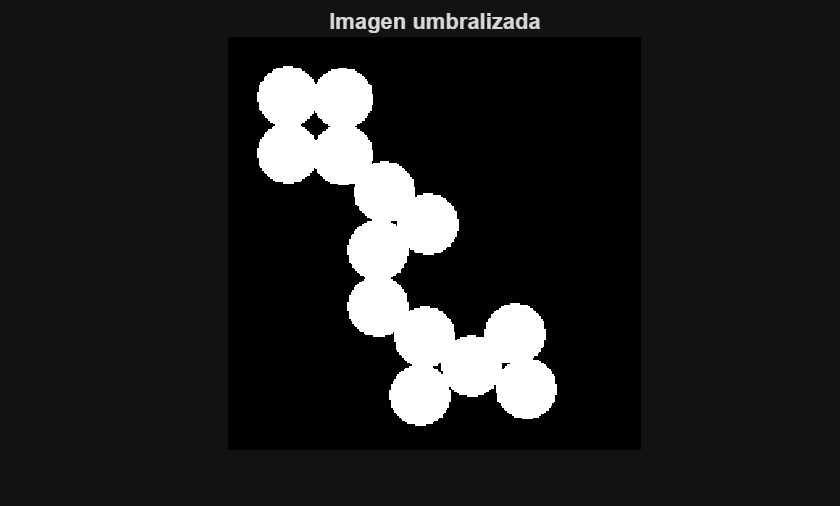


BW = imread('.\Imagenes\circles.png'); % Ya es binaria, no hace falta umbralizar

figure;
imshow(BW); title('Imagen umbralizada');

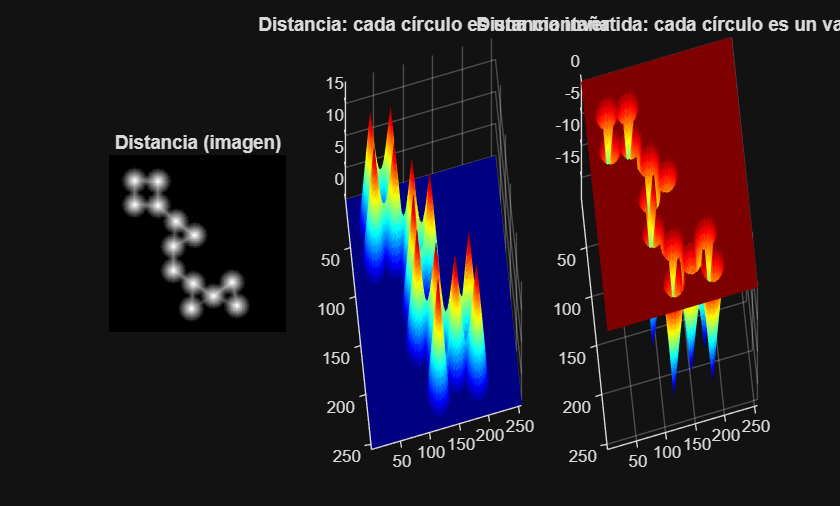


% Transformada de distancia
% A cada píxel del objeto se le asigna su distancia al fondo más cercano.
% bwdist calcula la distancia al píxel BLANCO más cercano, por eso se lo aplicamos a ~BW 
% (el fondo pasa a ser blanco) -> obtenemos la distancia de cada píxel del círculo al fondo.
D = bwdist(~BW);


figure;
subplot(1,3,1), imshow(D, []); title('Distancia (imagen)');

subplot(1,3,2), surf(D, 'EdgeColor', 'none');
axis ij;            % fila 1 arriba, igual que en la imagen -> misma orientación
axis tight;         % ajusta los ejes a la imagen
view(-10, 65);      % casi desde arriba y un poco inclinada: cada pico encima de su círculo
colormap(gca, jet);
title('Distancia: cada círculo es una montaña');

subplot(1,3,3), surf(-D, 'EdgeColor', 'none');
axis ij; axis tight; view(-10, 65);
colormap(gca, jet);
title('Distancia invertida: cada círculo es un valle');


%% Watershed directo (sin preprocesado)
% Invertimos la distancia: las cimas (centros) pasan a ser valles, que es lo que inunda watershed.
relieve = -D;

% (Si a una matriz de etiquetas le pones una máscara lógica entre paréntesis, MATLAB busca y modifica únicamente los píxeles donde la máscara vale 1. 
% Esto es lo que se hace con las mascaras relieve y L para modificar el fondo (valores a 1 tras invertir la imagen))
relieve(~BW) = -Inf; %El fondo de la imagen se pone a −∞, el valle más profundo posible. Así el fondo forma su propia cuenca y no se mezcla con los círculos.

L = watershed(relieve); % cada cuenca recibe una etiqueta 1, 2, 3...; las líneas divisorias valen 0
L(~BW) = 0; % El fondo se pone a 0

numRegiones = max(L(:)); % Como las regiones están numeradas 1, 2, 3…, la etiqueta más alta indica cuántas hay.
disp(['Regiones obtenidas sin preprocesado: ' num2str(numRegiones)]);

Regiones obtenidas sin preprocesado: 22


numRegionesCirculos = numel(unique(L(L > 0))); % Quitar huecos y fondo (sólo contar los círculos)
disp(['Regiones sin contar huecos y fondo: ' num2str(numRegionesCirculos)]); 

Regiones sin contar huecos y fondo: 17


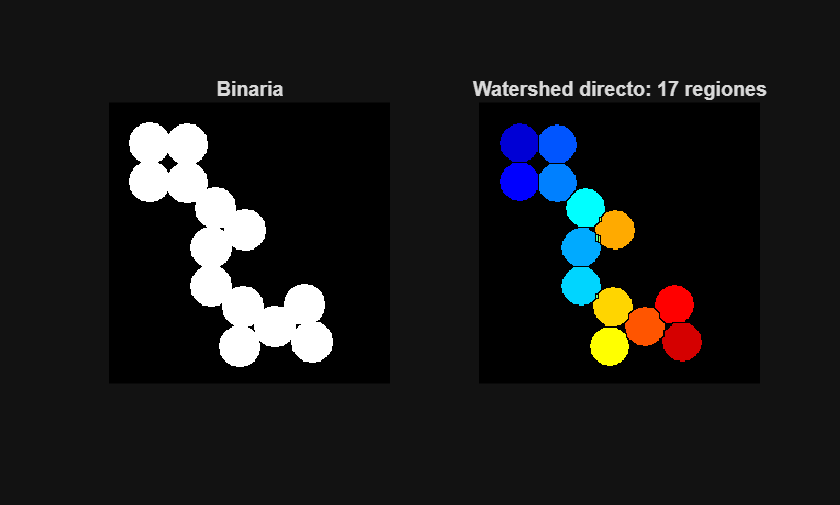


figure;
subplot(1,2,1), imshow(BW); title('Binaria');
subplot(1,2,2), imshow(label2rgb(L, 'jet', 'k')); % cada región de un color, fondo negro
title(['Watershed directo: ' num2str(numRegionesCirculos) ' regiones']);



%% Reducir la sobresegmentación con preprocesado morfológico (marcadores)
% Idea (apuntes): obtener regiones que sabemos CON SEGURIDAD que son objeto -> marcadores.
% Erosionando mucho, cada círculo queda reducido a un "núcleo" en su centro y los círculos
% que se tocan se separan. Cada núcleo será el ÚNICO punto de partida del agua en ese círculo.
radio = 12;
marcadores = imerode(BW, strel('disk', radio));

% imimposemin obliga a que los únicos valles del relieve estén en los marcadores (elimina los mínimos falsos que causaban la sobresegmentación)
relieve2 = imimposemin(-D, marcadores);
relieve2(~BW) = -Inf; 

L2 = watershed(relieve2);
L2(~BW) = 0; % SOLO en el fondo, pon 0

numRegiones2 = max(L2(:));
numRegionesCirculos2 = numel(unique(L2(L2 > 0))); % Quitar huecos y fondo (sólo contar los círculos)
disp(['Regiones con marcadores (erosión radio ' num2str(radio) '): ' num2str(numRegiones2)]);

Regiones con marcadores (erosión radio 12): 18


disp(['Regiones sin contar huecos y fondo: ' num2str(numRegionesCirculos2)]); 

Regiones sin contar huecos y fondo: 13


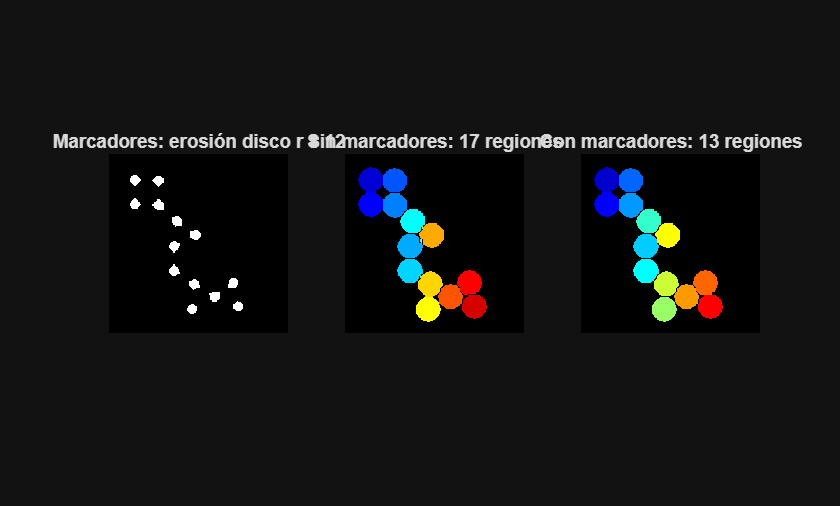


figure;
subplot(1,3,1), imshow(marcadores); title(['Marcadores: erosión disco r = ' num2str(radio)]);
subplot(1,3,2), imshow(label2rgb(L,  'jet', 'k')); title(['Sin marcadores: ' num2str(numRegionesCirculos) ' regiones']);
subplot(1,3,3), imshow(label2rgb(L2, 'jet', 'k')); title(['Con marcadores: ' num2str(numRegionesCirculos2) ' regiones']);

Se ha segmentado la imagen “circles.png”, formada por 13 círculos que se tocan entre sí, mediante la transformada watershed. La imagen original ya es binaria, por lo que no es necesario umbralizarla. A continuación se calculó la transformada de distancia (bwdist), en la que cada píxel del objeto toma el valor de su distancia al fondo, de modo que los centros de los círculos aparecen como máximos. Se invirtió para convertirlos en mínimos (cuencas) y se aplicó watershed. Hay que tener en cuenta que entre los círculos que se tocan quedan huecos de fondo "encerrados" entre círculos y sin conexión con el fondo exterior. Debido a que watershed es segmentación basada en regiones, estos huecos deben considerarse regiones separadas, aunque luego se puedan fiiltrar. El resultado presenta sobresegmentación: se obtienen 17 regiones en lugar de 13, debido a regiones diminutas situadas en las uniones entre círculos. Su origen es que el agua sale de todos los valles del relieve, por muy pequeños que sean: si los estrechamientos entre círculos generan pequeños mínimos locales falsos, watershed trata cada uno como un valle más, dándole su propio color de agua. 

Para eliminarlo se aplicó un preprocesado morfológico: erosionando la imagen binaria con un disco de radio 12 se obtiene un núcleo en el centro de cada círculo, que se utiliza como marcador; imponiendo que los únicos mínimos del relieve sean estos marcadores (imimposemin), watershed obtiene correctamente las 13 regiones.

**2. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

- Detecte los bordes mediante Canny. Utilice controles deslizantes para modificar los umbrales y/o σ, visualice el efecto de las distintas configuraciones y comente cómo afecta cada parámetro al resultado.

- Intente conectar los bordes separados por pequeños huecos mediante dilatación (`imdilate`). Visualice el resultado.

- Rellene los contornos obtenidos.

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel' ``y` compare los resultados Canny - Sobel. Justifique las diferencias.

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

**3. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, detecte y represente los 7 segmentos de recta más largos de la imagen **'despacho1.jpg'**. 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre los segmentos detectados.

- Calcule el número de picos `size(P,1)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

**4. Detección de circunferencias utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y represente el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?